# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 2, Part 2 : the best linear controller - Bellman, LQR, Riccati, DARE (blocks 3 to 6)**

Run M2_1_Flight_Data_DMDc first (it creates `dmdc_model.mat`).

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Block 3 - Bellman equation

**What is "good flying"?** We add up, over the whole flight, the squared errors and the squared effort:


$$J = \sum_{k=0}^{\infty}\left(x_k^T Q\,x_k + u_k^T R\,u_k\right) \qquad \rightarrow (M2.5)$$


$Q$ says how much each error hurts, $R$ how much each push costs. **Bryson's rule**: $Q_{ii} = 1/x_{i,max}^2$ and $R_{jj} = 1/u_{j,max}^2$, so a 50 cm position error costs as much as a 1 m/s speed error or 5 N of extra thrust.

**Principle of optimality (Bellman).** The lowest cost from here = best first move + lowest cost from where it leads:


$$V(x_k) = \min_{u_k}\left[x_k^T Q x_k + u_k^T R u_k + V(x_{k+1})\right], \qquad x_{k+1} = Ax_k + Bu_k \qquad \rightarrow (M2.6)$$


For a linear model and a quadratic cost the answer is again quadratic:


$$V(x) = x^T P\,x \qquad \rightarrow (M2.7)$$


**Toy example (scalar).** $x_{k+1} = 1.1x_k + 0.5u_k$ (grows 10 % per step on its own), $q = r = 1$, next value $V(x) = 1\cdot x^2$, now $x = 1$:


$$\textrm{cost}(u) = 1 + u^2 + (1.1 + 0.5u)^2, \qquad \frac{d}{du} = 2u + (1.1 + 0.5u) = 0 \Rightarrow u^* = -\frac{1.1}{2.5} = -0.44, \qquad V(1) = 1.968$$


a = 1.1;  b = 0.5;  q = 1;  r = 1;
cost = @(u) q*1^2 + r*u.^2 + 1*(a*1 + b*u).^2;
u_star = -a*b/(r + b^2)                 % by hand

u_star = -0.4400

[u_search, V1] = fminsearch(cost, 0)   % by the inbuilt optimiser

u_search = -0.4400

V1 = 1.9680

## Block 4 - Linear Quadratic Regulator (LQR)

Put $V(x_{k+1}) = (Ax + Bu)^T P (Ax + Bu)$ into (M2.6) and set the derivative with respect to $u$ to zero:


$$2Ru + 2B^T P(Ax + Bu) = 0 \quad \Rightarrow \quad (R + B^T P B)\,u = -B^T P A\,x$$



$$K = \left(R + B^T P B\right)^{-1} B^T P A \qquad \rightarrow (M2.8)$$



$$u_k = -K\,x_k \qquad \rightarrow (M2.9)$$


$R + B^TPB$ is positive definite, so this is a true minimum. The best controller is just a matrix.

## Block 5 - Riccati recursion

Put $u^* = -Kx$ back into (M2.6). The new value is again $x^T P_{new} x$ with


$$P_{k+1} = A^T P_k A - A^T P_k B\left(R + B^T P_k B\right)^{-1} B^T P_k A + Q \qquad \rightarrow (M2.10)$$


Each iteration looks one more step into the future. Scalar toy: $P_{k+1} = 1 + 1.21P_k - \frac{(0.55P_k)^2}{1 + 0.25P_k}$, $P_0 = 1$.

Pk = zeros(1, 36);  Pk(1) = 1;
for k = 1:35
    Pk(k+1) = q + a^2*Pk(k) - (a*b*Pk(k))^2/(r + b^2*Pk(k));
end
k = (0:8)';  P_k = Pk(1:9)';
table(k, P_k)

ans = 9×2 table
    k     P_k  
    _    ______

    0         1
    1     1.968
    2     2.596
    3    2.9049
    4    3.0362
    5    3.0885
    6    3.1088
    7    3.1166
    8    3.1196


P_limit = Pk(end)

P_limit = 3.1215

## Block 6 - DARE (Discrete Algebraic Riccati Equation)

When $P_k$ stops changing, $P_{k+1} = P_k = P$:


$$P = A^T P A - A^T P B\left(R + B^T P B\right)^{-1} B^T P A + Q \qquad \rightarrow (M2.11)$$


Scalar toy: multiply by $(1 + 0.25P)$ and simplify: $0.25P^2 - 0.46P - 1 = 0$, so


$$P = \frac{0.46 + \sqrt{0.46^2 + 1}}{0.5} = 3.1215, \qquad K = \frac{ab\,P}{r + b^2P} = 0.9643, \qquad a - bK = 0.6179$$


Without control the state grows 10 % per step; with LQR it **shrinks** 38 % per step.

P_dare = (0.46 + sqrt(0.46^2 + 1))/0.5

P_dare = 3.1215

K      = a*b*P_dare/(r + b^2*P_dare)

K = 0.9643

closed_loop = a - b*K

closed_loop = 0.6179

**Optimal cost.** Along the closed loop, $x_k^TPx_k - x_{k+1}^TPx_{k+1} = x_k^TQx_k + u_k^TRu_k$. Adding up all steps (everything in between cancels) gives $J^* = x_0^T P\,x_0$.

## The drone

clearvars -except PUBLISH ready
load('dmdc_model.mat', 'A', 'B', 'dt');
x_max = [0.5*ones(3,1); 1.0*ones(3,1); 0.2; 0.2; 0.5; 1.0*ones(3,1)];   % m, m/s, rad, rad/s
u_max = [5; 0.2; 0.2; 0.05];                                             % N, N m
Q = diag(1./x_max.^2);
R = diag(1./u_max.^2);

**Riccati recursion** starting from $P_0 = Q$:

Pk = Q;  change = [];
for it = 1:5000
    Kk = (R + B'*Pk*B) \ (B'*Pk*A);
    Pn = A'*Pk*A - A'*Pk*B*Kk + Q;  Pn = (Pn + Pn')/2;
    change(it) = norm(Pn - Pk, 'fro')/norm(Pn, 'fro');
    Pk = Pn;
    if change(it) < 1e-12, break, end
end
iterations = it

iterations = 236

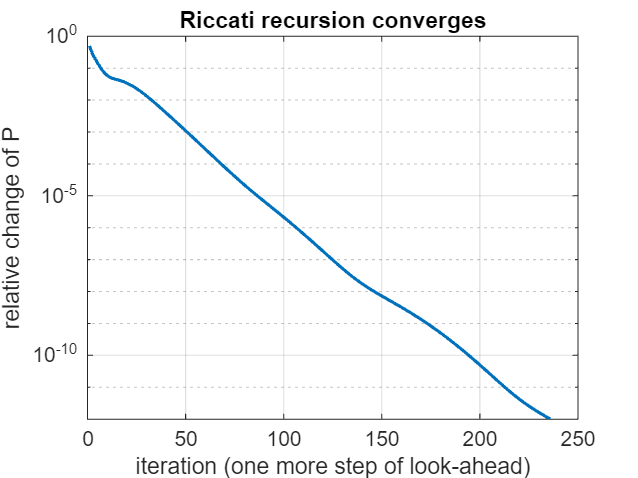

figure
semilogy(change, LineWidth=1.5); grid on
xlabel("iteration (one more step of look-ahead)"); ylabel("relative change of P"); title("Riccati recursion converges")

**DARE solved directly** (stable eigenvectors, no toolbox) and the LQR gain:

P = DroneLib.dare(A, B, Q, R);
K = (R + B'*P*B) \ (B'*P*A);
dare_residual   = norm(A'*P*A - A'*P*B*K + Q - P)/norm(P)

dare_residual = 6.5150e-14

recursion_vs_dare = norm(Pk - P)/norm(P)

recursion_vs_dare = 1.6121e-11

spectral_radius_open   = max(abs(eig(A)))         % >= 1 : not stable alone

spectral_radius_open = 1.0171

spectral_radius_closed = max(abs(eig(A - B*K)))   % < 1  : LQR makes it stable

spectral_radius_closed = 0.9496

**Reading the gain.** Two of the 48 numbers of $K$ ($u = -Kx$):

thrust_from_z  = -K(1, [3 6])        % dT = -(..)dz - (..)vz : too high -> less thrust

thrust_from_z =    -9.0385   -6.9165


roll_from_y    = -K(2, [2 5 7 10])   % tau_x from y, v_y, roll, roll rate

roll_from_y =     0.2726    0.3213   -1.4443   -0.2756


**Check of the optimal cost** $J^* = x_0^TPx_0$ by simulating the learned model from 50/30/20 cm away:

x = [0.5; -0.3; 0.2; zeros(9,1)];  x0 = x;  Jsim = 0;  X = x;
for k = 1:2000
    u = -K*x;
    Jsim = Jsim + x'*Q*x + u'*R*u;
    x = A*x + B*u;  X(:,end+1) = x;
end
J_simulated = Jsim

J_simulated = 41.4373

J_predicted = x0'*P*x0

J_predicted = 41.4373

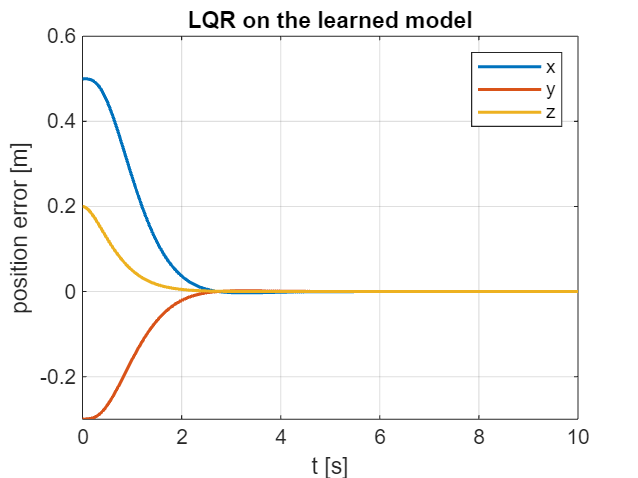

figure
plot((0:size(X,2)-1)*dt, X(1:3,:), LineWidth=1.5); xlim([0 10]); grid on
xlabel("t [s]"); ylabel("position error [m]"); legend("x","y","z"); title("LQR on the learned model")

**In the real drone:** LQR is a table. Every 40 ms: $u = u_{trim} - Kx$ (one 4 x 12 product). Its weakness: it knows nothing about limits such as `max_velocity` = 1 m/s. That is what MPC (M2_3) adds.

P_dare = P;
save('dmdc_model.mat', 'Q', 'R', 'P_dare', 'K', '-append');

if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end